% load animal data
clear

AnimalID = "stdS3"

AnimalID = "stdS3"


ExperimentFolder = "constant_sound"

ExperimentFolder = "constant_sound"


% Set input folder

InputDirectory = "/media/sthitapati/D/Behavioural_Data/matlab_output";


InputFolder = strcat(InputDirectory, "/", ExperimentFolder, "/",AnimalID)

InputFolder = "/media/sthitapati/D/Behavioural_Data/matlab_output/constant_sound/stdS3"

% check if the file to be analyzed exists

GetDir = dir(InputFolder);

if isempty(GetDir)
    disp("There is no data to analyze: Go back to data curation");
end

file_query = dir(strcat(InputFolder, "/*.mat"));

if ~isempty(file_query) && contains(file_query.name, AnimalID)
    load(strcat(InputFolder, "/matlab_output_", AnimalID, ".mat"));
else
    disp("There is no data to analyze: Go back to data curation");
end

% head(bpodTable)

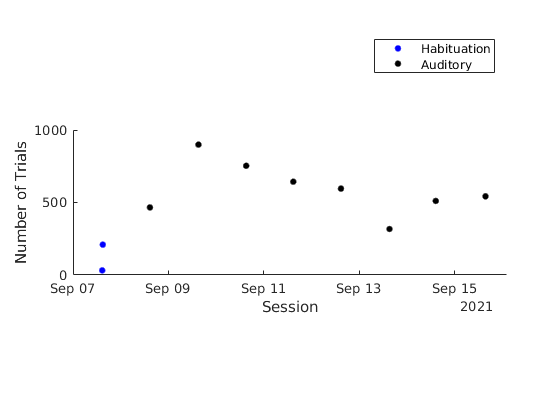

% Plot training day in X-axis and Number of trials in Y-axis
% TODO: Specification and beautification of plot

num_trials_table = rowfun(@max, bpodTable, "InputVariables", "TrialIndex", ...
    "GroupingVariables", ["DateTime", "Protocol"], "OutputVariableNames", "num_trials");

figure
hold on
gscatter(num_trials_table.DateTime, num_trials_table.num_trials, ...
    num_trials_table.Protocol, 'bk')

pbaspect([3 1 1])

xlabel("Session")
ylabel("Number of Trials")

ylim([0, max(num_trials_table.num_trials)+100])

hold off


% save figure

Start individual analysis code from here

TODO: Delete useless code below once the pipeline is complete

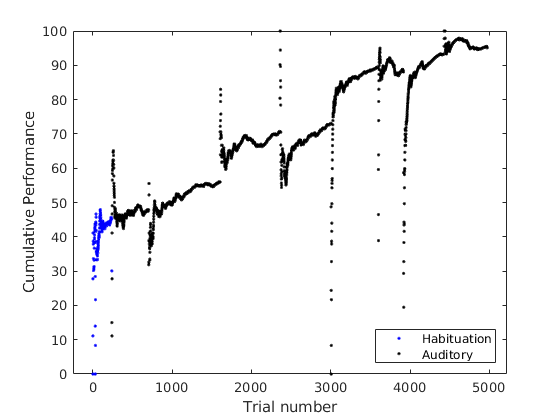

% Plot cumulative performance across trails with each session a different colour
% Find unique Protocols

unique_protocols = bpodTable.Protocol;

% x-axis: TrialIndex grouped according to Protocol
trial_number = (1: length(bpodTable.TrialIndex))';
% y-axis: Cumulative performance
cumulative_performance = bpodTable.CumulativePerformance;
% Smooth y data
cumulative_performance = smoothdata(cumulative_performance, "SmoothingFactor", 0.01);
% label and beutify the plot

cum_performance_table = table(trial_number,cumulative_performance, unique_protocols);

gscatter(cum_performance_table.trial_number, cum_performance_table.cumulative_performance, ...
    cum_performance_table.unique_protocols, "bk")


ylim([0, 100])

xlabel("Trial number")
ylabel("Cumulative Performance")

legend("Location", "southeast")

% Plot data for the session in which inference was run
% for bpodTable.SessionDate == "13-Sep-2021"

inference_day = bpodTable(bpodTable.SessionDate == "13-Sep-2021", :);

performance = (movmean(inference_day.FirstPokeCorrect, 50, "omitnan")) * 100;

cumulative_performance = smoothdata(inference_day.CumulativePerformance, "SmoothingFactor", 0.01)

cumulative_performance =   100.0000
  100.0000
   96.0000
   92.6667
   89.8095
   87.3095
   85.0873
   87.0873
   88.6025
   89.7929


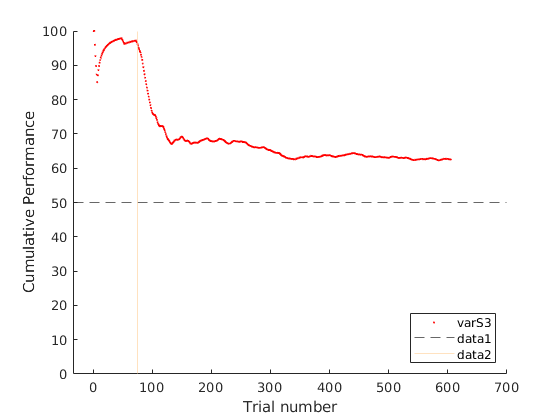


figure
hold on
gscatter(inference_day.TrialIndex, cumulative_performance, inference_day.AnimalID, "r", "o", 1)

yline(50, '--')
xline(75, '-', "Color", '#ffd6a5')

ylim([0, 100])

xlabel("Trial number")
ylabel("Cumulative Performance")


legend("Location", "southeast")
hold off

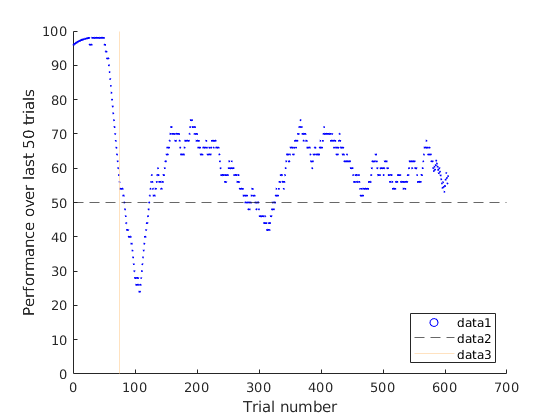


figure
hold on
scatter(inference_day.TrialIndex, performance, 1, "blue")

yline(50, '--')
xline(75, '-', "Color", '#ffd6a5')

ylim([0, 100])

xlabel("Trial number")
ylabel("Performance over last 50 trials")

legend("Location", "southeast")
hold off

% TODO: Plot trial type (high and low) vs percent right across sessions:
% plot for scatter only non-psychometric ones

% Group them according to session and trialtype

percent_right_table = rowfun(@measurePerformance,bpodTable, "InputVariables","FirstPokeCorrect", ...
    "GroupingVariables", ["DateTime", "TrialHighPerc"], ...
    "OutputVariableNames", "performance");

% Plot trialtype vs percent right across sessions

gscatter(percent_right_table.DateTime, percent_right_table.performance, ...
    percent_right_table.TrialHighPerc, "cr")

ylim([0, 1])

legend(["Low", "High"], "Location", "southeast")
datetick('x', "dd/mm")



% plot bar graph of the same thing


% Plot performance heatmap

% prepare data
low_data = percent_right_table(percent_right_table.TrialHighPerc == 2, :);
high_data = percent_right_table(percent_right_table.TrialHighPerc == 98, :);

performance_heatmap = [low_data.performance'; high_data.performance'];

h = imagesc(performance_heatmap);

% TODO: get rid of axes
% label
% put custom colormap and colorbar

% Group them according to session and sound amplitude

percent_right_table = rowfun(@measurePerformance,bpodTable(bpodTable.TrialHighPerc == 2, :), ...
    "InputVariables","FirstPokeCorrect", ...
    "GroupingVariables", ["DateTime", "SoundAmplitude"], ...
    "OutputVariableNames", "performance");

gscatter(percent_right_table.DateTime, percent_right_table.performance, ...
    percent_right_table.SoundAmplitude)

ylim([0, 1])
legend('Location', "bestoutside")

percent_right_table(percent_right_table.DateTime == '07-Sep-2021 15:44:12', :)

% Group them according to session and sound amplitude

percent_right_table = rowfun(@measurePerformance,bpodTable(bpodTable.TrialHighPerc == 98, :), ...
    "InputVariables","FirstPokeCorrect", ...
    "GroupingVariables", ["DateTime", "SoundAmplitude"], ...
    "OutputVariableNames", "performance");

gscatter(percent_right_table.DateTime, percent_right_table.performance, ...
    percent_right_table.SoundAmplitude)

ylim([0, 1])
legend('Location', "bestoutside")


% plot session vs rightbias

% Choose only psychometric trials

PsychTrials = bpodTable(bpodTable.Protocol == "Aud_Psycho", ...
    {'TrialHighPerc', 'FirstPoke', 'DateTime', 'Stimulation', 'Contingency'})

% TODO write a function handle to extract desired sessions when given
% datetime values as inputs
% PsychTrials_exctracted = PsychTrials(PsychTrials.DateTime == {'08-Dec-2020 16:11:07','09-Dec-2020 13:40:19'}, :)


% Plot TrialHighPerc in x-axis as categories and percent right choice in y-axis
% calculate % right choice
% 1 is left 2 is right

% Prepare table for plotting

PerformanceTable = rowfun(@measurePerformance, PsychTrials, ...
    "InputVariables", ["FirstPoke","Contingency"], ...
    "GroupingVariables",["TrialHighPerc", "DateTime"], ...
    "OutputVariableNames",["RightChoice", "Total", "PercentCorrect", "PercentRight"])


all_sessions = unique(PerformanceTable.DateTime);

% Fit to logistic regression


range_for_logitFit = 0:1:100;
[logitCoef, dev, stats] = glmfit(PerformanceTable.TrialHighPerc, [PerformanceTable.RightChoice, PerformanceTable.Total] , ...
    "binomial", "link", "logit");
[logitFit, dylo, dyhi] = glmval(logitCoef, range_for_logitFit, "logit", stats, "confidence", 0.95);
err = [dylo, dyhi];

% Make figures
num_col = 4;
M = mod(length(all_sessions), 4);
rows = ceil((length(all_sessions) + M)/ num_col);

figure(2);
figure("Position", [1, 1, 2400, 2400]);

for i = 1: length(all_sessions)
        P1 = PerformanceTable(PerformanceTable.DateTime == all_sessions(i), :);
        range_for_logitFit = 0:1:100;
        [logitCoef, dev, stats] = glmfit(P1.TrialHighPerc, [P1.RightChoice, P1.Total] , ...
                                    "binomial", "link", "logit");
        [logitFit, dylo, dyhi] = glmval(logitCoef, range_for_logitFit, "logit", stats, "confidence", 0.95);
                                        err = [dylo, dyhi];
    
        s = subplot(rows, num_col, i);
        plot_title = string(datestr(datenum(all_sessions(i))));
        plot_title = extractBefore(plot_title, " ");
        
        PlotPsychFunction(P1.TrialHighPerc, P1.PercentRightChoice, ...
                            range_for_logitFit, logitFit,dylo, dyhi);
        title(plot_title, "FontSize", 8, "FontWeight","normal");
        pbaspect([1.4 1 1]);
end





% bootstrap and plot crossvalidated models
% TODO: Write a function to plot with boostrapping

figure(3);

figure("Position", [1, 1, 2400, 2400]);
for i = 1: length(all_sessions)
        P1 = PerformanceTable(PerformanceTable.DateTime == all_sessions(i), :);
        range_for_logitFit = 0:1:100;
        [logitCoef, dev, stats] = glmfit(P1.TrialHighPerc, [P1.RightChoice, P1.Total] , ...
                                    "binomial", "link", "logit");
        [logitFit, dylo, dyhi] = glmval(logitCoef, range_for_logitFit, "logit", stats, "confidence", 0.95);
                                        err = [dylo, dyhi];
    
        s = subplot(rows, num_col, i);
        plot_title = string(datestr(datenum(all_sessions(i))));
        plot_title = extractBefore(plot_title, " ");
        
        PlotPsychFunctionBtStrp(P1.TrialHighPerc, P1.PercentRightChoice, ...
                            range_for_logitFit, logitFit,dylo, dyhi);
        title(plot_title, "FontSize", 8, "FontWeight","normal");
        
        pbaspect([1.4 1 1]);
end


% Make a matrix of psychometric plots for each session of the animals
% accumulate as sessions as columns and difficulty as rows
%TODO: Write a function for Matrix plots

untr = unique(PerformanceTable.TrialHighPerc);
undt = unique(PerformanceTable.DateTime);
PsychMat = zeros(length(untr), length(undt));
for i = 1:length(untr)
    PsychMat(i,:) = PerformanceTable.PercentRightChoice(PerformanceTable.TrialHighPerc == untr(i));
end




% Write a code to subplot categorical description on top of the plot
% make an array of optostim values in a particular session

Sessions = string(datestr(datenum(undt)));

catTable = table();
warning("off")
for i =1:length(Sessions)
    catTable.Session(i) = Sessions(i);
    idx = find(PsychTrials.DateTime == Sessions(i));
    catTable.Stim(i) = unique(PsychTrials.Stimulation(idx));
    catTable.Muscimol(i) = unique(PsychTrials.Muscimol(idx));
end


Sessions_label = extractBefore(Sessions, " ");
A = zeros(1, length(catTable.Stim));
for i = 1: length(catTable.Stim)
    if catTable.Stim(i) == "Both"
        A(1, i) = 1;
    else
        A(1, i) = 0;
    end
end

A(A == 0) = NaN;
figure(4);
%% TODO Automate ax2 positioning so that it can be used within a loop
ax1 = axes('Position',[0.13 0.75 0.7750 0.08]);
ax2 = axes('Position',[0.13 0.11 0.7750 0.8150]);

% linkaxes([ax1 ax2], 'xy')

imagesc(ax2, PsychMat);
ax2.PlotBoxAspectRatio = [2 0.8 1];

xlabel("Session");
ylabel("Percent High Tone");
ax2.XTick = (1:size(PsychMat, 2)) ;
ax2.YTick = (1:size(PsychMat, 1)) ;
ax2.XTickLabel = Sessions_label';
ax2.YTickLabel = untr;
ax2.XTickLabelRotation = 90;

cb = colorbar(ax2);
cb.Position = [0.91 0.3381 0.015 0.357]; 
cb.Label.String = "Right Choice";


xAx = ax2.XAxis;
xAx.TickLength = [0 0];

yAx = ax2.YAxis;
yAx.TickLength = [0.004 0];

X = 1: length(A);
s = scatter(ax1, X, A);
s.Marker = "hexagram";
s.MarkerFaceColor = "c";
s.MarkerEdgeColor = "b";

          
ax1.XLim = [0.5 length(A)+0.5];
ax1.XAxis.Visible = "off";
ax1.YAxis.Visible = "off";
xlabel(ax1, "none");
ylabel(ax1, "none");
legend(ax1, "LTD (13 Hz)", "Location", "best");


% Plot Cumulative performace across all trials, individual sessions to be
% color coded
% Plot Right bias across all sessions
% Bar graph showing session time in X-axis and percent correct Y-axis
% Split data for conditions: e.g. Pf leison

% Function definitions

function percent_correct = measurePerformance(first_poke_correct)

    percent_correct = nnz(first_poke_correct)/ numel(first_poke_correct);

end

function [RightCount, Total, PercentRight] = measureRightBias(FirstPoke)
    RightCount = nnz(FirstPoke == 2);
    Total = numel(FirstPoke);
    PercentRight = RightCount ./ Total;
end


% Function to bootstrap and fit to a logistic regression
function bfit = glmBfit(diff, perf)

bfit = glmfit(diff, perf, "binomial", "link","logit");

end


% Function to plot the data

function PlotPsychFunction(difficulty, performance,range_for_logitFit, logitFit,dylo, dyhi)

ax = gca;

hold on

plot(difficulty, performance, "ob", "MarkerFaceColor", "b")
plot(range_for_logitFit, logitFit, "k-")
plot(range_for_logitFit, logitFit - dylo, "r--")
plot(range_for_logitFit, logitFit + dyhi, "r--")

xlabel("Percent High Tone");
ylabel ("Right Choice");
xtickangle(45);

ax.XTick = difficulty;

xAx = ax.XAxis;
xAx.Direction = "reverse";
hold off

end

function PlotPsychFunctionBtStrp(difficulty, performance,range_for_logitFit, logitFit,dylo, dyhi) 

ax = gca;
% c = uisetcolor;
c = [0.75 0.73 0.99];
hold on

for i = 1:100
    b2 = bootstrp(1, @glmBfit, difficulty, performance);
    yfitBoot(:, i) = glmval(b2', range_for_logitFit, "logit");
    plot(range_for_logitFit, yfitBoot(:, i), '-', "Color", c);  
end

plot(difficulty, performance, "ob", "MarkerFaceColor", "b")
plot(range_for_logitFit, logitFit, "k-")
plot(range_for_logitFit, logitFit - dylo, "r--")
plot(range_for_logitFit, logitFit + dyhi, "r--")


xlabel("Percent High Tone");
ylabel ("Right Choice");
xtickangle(45);
ax.XTick = difficulty;

xAx = ax.XAxis;
xAx.Direction = "reverse";
hold off

end